# Winner-take-all

clear;
clc;
addpath('../funcs');
load ../../data/all4000_onlyAttn_0_0.5_0_0.05_Iattn_0.02.mat;
filepath = '../../paper/figure3_new/';

% scatter(0.12, 0.04,markSZ,"o",'LineWidth',2,'MarkerEdgeColor','k');
% scatter(0.1, 0.03,markSZ,"+",'LineWidth',2,'MarkerEdgeColor','k');
% scatter(0.3, 0.02,markSZ,"square",'LineWidth',2,'MarkerEdgeColor','k');
% scatter(0.36, 0.0395,markSZ,"^",'LineWidth',2,'MarkerEdgeColor','k');

## Time-course: circle

Delta_E = 0.12;
Delta_I = 0.04;
Iattn = 0.02;
time = 4000;
dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

[r,~,~] = onlyAttn(Delta_E, Delta_I, Iattn, time);
r = r*1000;

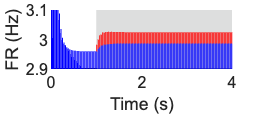

pop = 1;
figure();

hold on;
 
recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.5);
% hold on;
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.5);


hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_only');
print(filename, '-dpng', '-r600');

% print(filename', '-dsvg', '-r600');

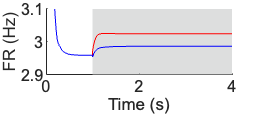

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_only_env');
print(filename, '-dpng', '-r600');

% print(filename', '-dsvg', '-r600');

Delta_E = 0.12;
Delta_I = 0.04;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

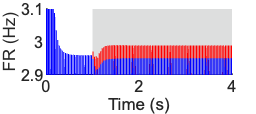

pop = 1;
figure();

hold on;
 
recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.5);

hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_both');
print(filename, '-dpng', '-r600');

% print(filename', '-dsvg', '-r600');

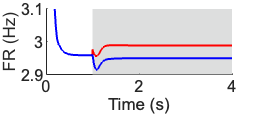

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_both_env');
print(filename, '-dpng', '-r600');

% print(filename', '-dsvg', '-r600');

## Time-course: plus

Delta_E = 0.1;
Delta_I = 0.03;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

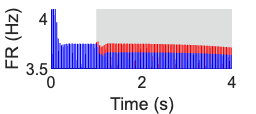

pop = 1;
figure();

hold on;
 
recX = [1 4 4 1];
recY = [0 0 200 200];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.5);

hold off;
axis([0 4 3.5 4.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_plus_L23E');
% print(filename, '-dpng', '-r600');
% print(filename', '-dsvg', '-r600');

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([0 4 3.5 4.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_plus_L23E_env');
print(filename, '-dpng', '-r600');
% print(filename', '-dsvg', '-r600');

## Time-course: square

Delta_E = 0.3;
Delta_I = 0.02;


## Time-course: Triangle

Delta_E = 0.36;
Delta_I = 0.0395;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

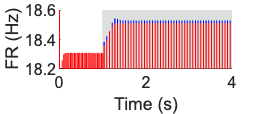

pop = 1;
figure();

hold on;
 
recX = [1 4 4 1];
recY = [0 0 200 200];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.5);

hold off;
axis([0 4 18.2 18.6]);
xlabel("Time (s)");
ylabel("FR (Hz)");

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_tri_L23E');
% print(filename, '-dpng', '-r600');
% print(filename', '-dsvg', '-r600');